# **PRACTICE 4. PARAMETRIC CLASSIFICATION**

## Grado en Ingeniería Informática - Reconocimiento de Patrones

## Fernando M. Quintana Velázquez - Guillermo Bárcena González

# EXERCISE 1: MINIMUM DISTANCE CLASSIFICATION

Initialize the random generator seeds (rand and randn) to 0

clear all;
close all;
clc;
rng(0);

dGenerate two classes of  1000 elements each one using randnorm, the first with mean $m=\left\lbrack 0,0\right\rbrack$ and covariance matrix  $C=\left\lbrack \begin{array}{cc}
1 & 0\ldotp 8\\
0\ldotp 8 & 2
\end{array}\right\rbrack$and the second with mean $m=\left\lbrack 3,3\right\rbrack$and $C=\left\lbrack \begin{array}{cc}
1 & -0\ldotp 9\\
-0\ldotp 9 & 2
\end{array}\right\rbrack$and finally mix  the data (use the function shuffle). 

% set up classes:
m1 = [0,0];
C1 = [1 0.8; 0.8 2];
C1_chol = chol(C1); 
class1 = randn(1000,2)*C1_chol+repmat(m1,1000,1);

class1 = class1';

%% class 2
m2 = [3,3];
C2 = [1 -0.9; -0.9 2];
C2_chol = chol(C2);
class2 = randn(1000,2)*C2_chol+repmat(m2,1000,1);

class2 = class2';

y = [zeros(1,1000), ones(1,1000)];
data = [class1 , class2];

% shuffle classes:
[data,y] = shuffle(data, y);

- Decode a minimum distance classifier with the first 1600 data.

for i = 1:1600
    aux = data(:,i);
    d(1) = sum((aux-m1').^2);
    d(2) = sum((aux-m2').^2);
    [~, clase(i)] = min(d);
    clase(i) = clase(i)-1;
end
TasaError   = sum(clase~=y(1:1600))/length(clase)*100

TasaError = 3.4375

TasaAcierto = sum(clase==y(1:1600))/length(clase)*100

TasaAcierto = 96.5625

- Perform the previous point using the Mahalanobis distance, and compare the  results.

d_m(1,:) = d_mahal(data(:,1:1600),m1',C1');
d_m(2,:) = d_mahal(data(:,1:1600),m2',C2');
[~,clase]=min(d_m);
clase = clase - 1;
TasaError   = sum(clase~=y(1:1600))/length(clase)*100

TasaError = 2.1250

TasaAcierto = sum(clase==y(1:1600))/length(clase)*100

TasaAcierto = 97.8750

- How are the boundaries between the classes? Can you draw them?

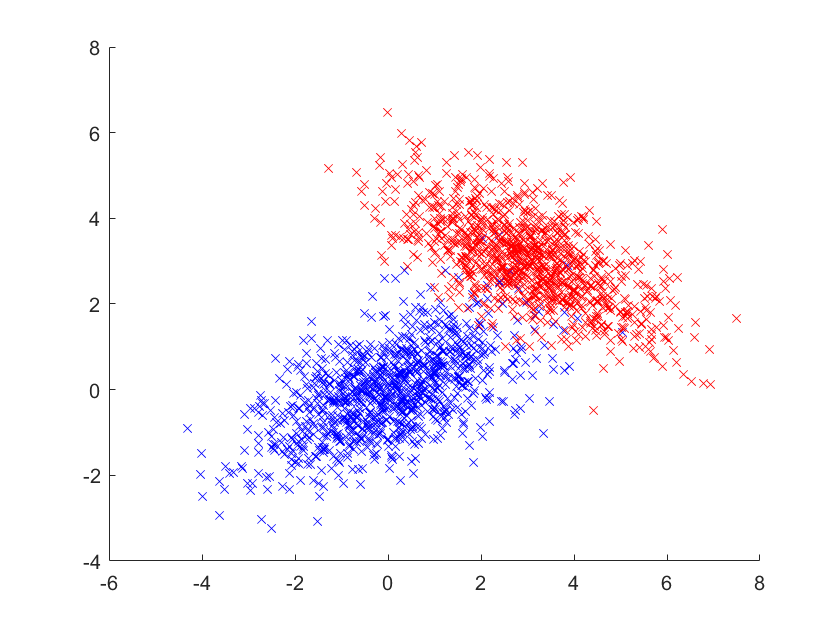

hold on;
plot(class1(2,:), class1(1,:),'Color','b','Marker','x', 'LineStyle','none');
plot(class2(2,:), class2(1,:),'Color','r','Marker','x', 'LineStyle','none');
hold off;

The classes cant get seperated perfectly by dawing a straight line because they have a small intersection, where a few datapoints overlap. The Mahalanobis distance works on this example better, because it acompensatens for oval shape of the two classes.